# 中点則                           

m=logspace(1,4,4);
Iext=repmat(log(2),size(m));     % 厳密解(log2)の配列
Imid=zeros(size(m));    % 中点則の計算結果用の配列 水位
n=size(m,2);
% 分点数を変えて積分
for k=1:n
Imid(k)=midpoint(@integrand,0,1,m(k)); 
end
%　絶対誤差
format shortE;
Emid=abs(Iext-Imid)./Iext

Emid =    4.4986e-04   4.5083e-06   4.5084e-08   4.5082e-10


# 台形則

% m=logspace(1,4,4);
Iext=repmat(log(2),size(m));     % 厳密解(log2)の配列
Itrp=zeros(size(m));    % 台形則の計算結果用の配列
n=size(m,2);
% 分点数を変えて積分
for k=1:n
Itrp(k)=trapezoid(@integrand,0,1,m(k)); 
end
%　絶対誤差
format shortE;
Etrp=abs(Iext-Itrp)./Iext

Etrp =    9.0056e-04   9.0167e-06   9.0168e-08   9.0171e-10


# シンプソン則

% m=logspace(1,4,4);
Iext=repmat(log(2),size(m));     % 厳密解(log2)の配列
Ismp=zeros(size(m));    % シンプソン則の計算結果用の配列
n=size(m,2);
% 分点数を変えて積分
for k=1:n
Ismp(k)=simpson(@integrand,0,1,m(k)); 
end
%　絶対誤差
format shortE;
Esmp=abs(Iext-Ismp)./Iext

Esmp =    4.4004e-06   4.5073e-10   4.4367e-14   1.2654e-14


# グラフ

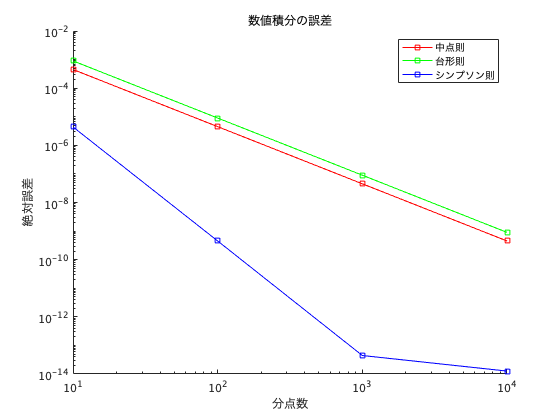

% 両対数グラフの指定
hold on;
plot(m, Emid, 'r-s'); % 中点則は赤色(r)
plot(m, Etrp, 'g-s'); % 台形則は緑色(b)
plot(m, Esmp, 'b-s'); % シンプソン則は青色(b)
graph=gca;             % グラフハンドルの取得
graph.YScale='log';    % y軸対数スケールの設定
graph.XScale='log';    % x軸対数スケールの設定
xlabel('分点数'); 
ylabel('絶対誤差');
legend('中点則','台形則','シンプソン則');
title('数値積分の誤差')
hold off;

# ファイルの最後に 関数定義を記述

被積分関数

function fout = integrand(x)
fout = 1/(1+x);
end


中点則，台形則，シンプソン則

function Mm = midpoint(f,a,b,m)
% 中点則　trapezoid
% 関数f(x), 区間[a, b], m個分割
h = (b - a) / m;
ci = a + h/2;
Mm=0;
for i = 0:m-1
    Mm = Mm + f(ci);
    ci = ci + h;
end
Mm=Mm*h;
end

function Tm = trapezoid (f,a,b,m)
% 台形則　trapezoid
% 関数f(x), 区間[a, b], m個分割
h = (b - a) / m;
ai = a + h;
Tm=(f(a)+f(b))/2;
for i = 1:m-1
    Tm = Tm+f(ai);
    ai = ai + h;
end
Tm=Tm*h;
end

function Sm = simpson (f,a,b,m)
% シンプソン則　simpson
% 関数f(x), 区間[a, b], m個分割
% 中点則と台形則を計算
  Mm= midpoint(f, a, b, m/2);
  Tm= trapezoid(f, a, b, m/2);
  Sm= (2/3 * Mm) + (1/3 * Tm);
% 中点則と台形則の結果を合成
% 穴埋め
end